# Jacobi Relaxation Method, 1D

This algorithm is designed to calculate the electric potential along the x axes between two plates of a capacitor utilizing the Jacobi relaxation method.

## Paramaters

dx = 0.005;
x = -0.1:dx:0.1;          % distance between the plates
v0 = 1;                   % lower bound
vL = 0;                   % grounded plate, upper bound

q = .0025;                % point charge [C]
eNaught = 8.85*10^-12;    % permittivity of free space
V = zeros(1,length(x));  
V(length(x)) = vL;        % set boundary condition
V(1) = v0;                % set boundary condition

chgPos = 0;                              % charge located at origin
[chgRow, chgCol] = find(x == chgPos);    % find charge position within x vector
Vold=V;                  

epsilon = 1*10^-5;        % convergence parameter
DV=1000;                  % iterative residual set to 100 to enter loop

Vnew=Vold;

## Calculations

while DV > epsilon
    for i = 2:(length(x)-1)
        if i == chgCol
            Vnew(i)=(1/2).*(((q*dx)/eNaught)+Vold(i-1)+Vold(i+1));
        else
            Vnew(i) = (1/2).*(Vold(i-1)+Vold(i+1));
        end
    end
 
    DV=sum(abs(Vnew-Vold));   % iterative residual
    Vold = Vnew;               
end

Vnew(chgRow, chgCol);

## Plotting

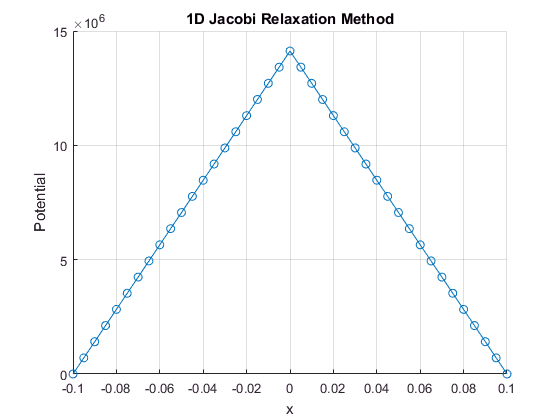

figure(1);
hold on;
grid on;

% label title and axes
title('1D Jacobi Relaxation Method');
xlabel('x [m]');
ylabel('Potential [V]');

%% plot
plot(x,Vnew,'-o');
hold off;